close("all"); clear; clc;

A1 = [
    -1,-4;
    4,-1
    ];

b = 0.05;

ns = 100;
ts = 0.02;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

X0 = ztope2d(0.1.*eye(2),[1;0]);

R = girard2005Alg(X0,A1,b,t);

sys = ss(A1,eye(2),eye(2),0);
traj = @(x0)lsim(sys,repmat(0.*t,[2,1]),t,x0);
trajx = @(x0)traj(x0)*[1;0];
trajy = @(x0)traj(x0)*[0;1];
plotTraj = @(x0)plot(trajx(x0),trajy(x0),"k:", ...
    "LineWidth",2 ...
    );

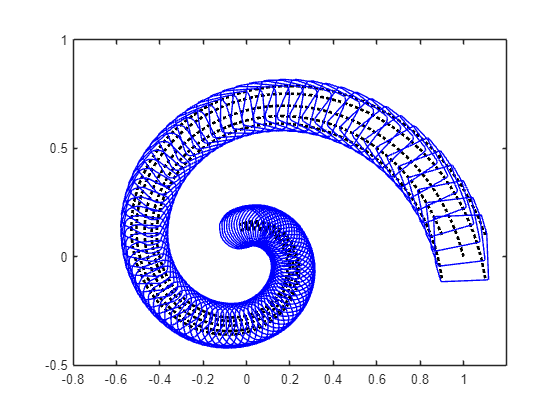

fig = figure();
axe = axes(fig);
% X0.plot();
hold(axe,"on");

x0 = [1,0;
    0.9,-0.1,;
    1.1,-0.1;
    0.9,0.1;
    1.1,0.1,
    ].';

cellfun(plotTraj,num2cell(x0,1));
hold(axe,"off");
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");
xlim([-0.8,1.2]);
ylim([-0.5,1]);

A = [
    -1,-4,0,0,0;
    4,-1,0,0,0;
    0,0,-3,1,0;
    0,0,-1,-3,0;
    0,0,0,0,-2
    ];
n = size(A,1);

p = [
    -1 - 4i;
    -1 + 4i;
    -3 + 1i;
    -3 - 1i;
    -2
    ];

pc = fliplr(poly(p));

A = [[zeros(1,n-1);eye(n-1)],-pc(1:end-1).'];

b = 0.01;

ns = 200;
ts = 0.005;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

x0 = [0.2,0.6,0,-0.8,0.7].';
X0 = ztope(0.1.*eye(n),x0);

R = girard2005Alg(X0,A,b,t,40);

sys = ss(A,ones(n,1),eye(n),0);
y = lsim(sys,0.*t,t,[1,0,0,0,0].');

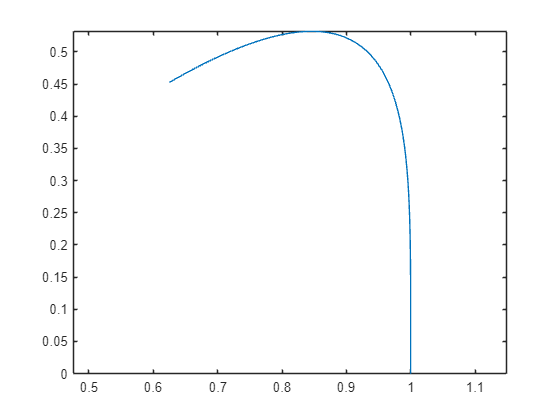

fig = figure();
axe = axes(fig);
plot(y(:,1),y(:,2));
% xlim(axe,[0,1.4]);
% ylim([-0.8,0.8]);
axis(axe,"equal");